# Introduction to Methanosarcina barkeri (iMG746)

doi:10.1038/msb4100046

if ~exist('iMG746.mat','file')
    % Load the Excel file
    filename = '~/drive/Methanogens/Methanosarcina/iMG746/iMG746.xlsx';
    Reactions = readtable(filename, 'Sheet', 1);
    Metabolites = readtable(filename, 'Sheet', 5);

    % Initialize COBRA model structure
    model = struct();
    
    % Assign fields
    model.rxns = Reactions.RxnName;  % Reaction names
    model.rxnNames = Reactions.RxnDescription;  % Reaction descriptions
    model.grRules = Reactions.Gene_reactionAssociation; % Gene-reaction associations
    model.rules = model.grRules;
    model.rxnFormulas = Reactions.Formula;
    model.subSystems = Reactions.Subsystem; % Subsystems
    model.lb = Reactions.LB; % Lower bounds
    model.ub = Reactions.UB; % Upper bounds
    model.rev = Reactions.Reversible; % Reversibility (1 = reversible, 0 = irreversible)
    model.c = Reactions.Objective; % Objective function coefficients
    model.comments = Reactions.Comments; % Additional comments
        % gene
    all_text = strjoin(Reactions.Genes, ' ');
    genes = strsplit(all_text);
    model.genes = unique(genes)';
    
    % Initialize stoichiometric matrix
    rxns = Reactions.Formula;
    mets = Metabolites.Metabolite_Name;
        % Extract all metabolites from reactions
    extracted_mets = unique(regexp(strjoin(rxns), '\S+\[c\]', 'match'));
    
    % Ensure mets contains all metabolites
    if ~isempty(setdiff(extracted_mets, mets))
        warning('Some metabolites in rxns are missing from mets. Expanding mets list.');
        mets = unique([mets; extracted_mets]); % Append missing metabolites
    end
    
    % Initialize stoichiometric matrix with correct size
    S = zeros(length(mets), length(rxns));
    
    % Process each reaction
    for j = 1:length(rxns)
        reaction = rxns{j};
        reactants_products = regexp(reaction, '<=>|->', 'split'); % Split reactants and products
    
        if length(reactants_products) < 2
            error(['Invalid reaction format in: ', reaction]);
        end
    
        % Identify and process reactants
        reactants = regexp(strtrim(reactants_products{1}), '[\+\s]', 'split');
        reactants = reactants(~cellfun('isempty', reactants));
    
        for k = 1:length(reactants)
            metabolite = regexp(reactants{ck}, '[a-zA-Z0-9-]+\[c\]', 'match', 'once');
            coeff = str2double(regexp(reactants{k}, '^\d+', 'match', 'once'));
            if isnan(coeff), coeff = 1; end % Default coefficient
            row_idx = find(strcmp(mets, metabolite)); % Find row index
    
            if ~isempty(row_idx)
                S(row_idx, j) = -coeff; % Reactants are negative
            else
                warning(['Metabolite not found in mets: ', metabolite]);
            end
        end
    
        % Identify and process products
        products = regexp(strtrim(reactants_products{2}), '[\+\s]', 'split');
        products = products(~cellfun('isempty', products));
    
        for k = 1:length(products)
            metabolite = regexp(products{k}, '[a-zA-Z0-9-]+\[c\]', 'match', 'once');
            coeff = str2double(regexp(products{k}, '^\d+', 'match', 'once'));
            if isnan(coeff), coeff = 1; end % Default coefficient
            row_idx = find(strcmp(mets, metabolite)); % Find row index
    
            if ~isempty(row_idx)
                S(row_idx, j) = coeff; % Products are positive
            else
                warning(['Metabolite not found in mets: ', metabolite]);
            end
        end
    end
    model.S = S;
    
    
    model.mets = Metabolites.Metabolite_Name;
    model.metNames = Metabolites.Metabolite_Description;
    model.metFormulas = Metabolites.Metabolite_Formula;

    iGM746 = model;
    % Save to MATLAB .mat file
    save('iGM746.mat', 'iMG746');
else
    model = readCbModel('iMG746.mat')
end

Error using readCbModel (line 232)
There were no valid models in the mat file.\n Please load the model manually via ' load iGM746.mat' and check it with verifyModel() to validate it.\nTry using convertOldStyleModel() before verifyModel() to bring the model structure up to date.

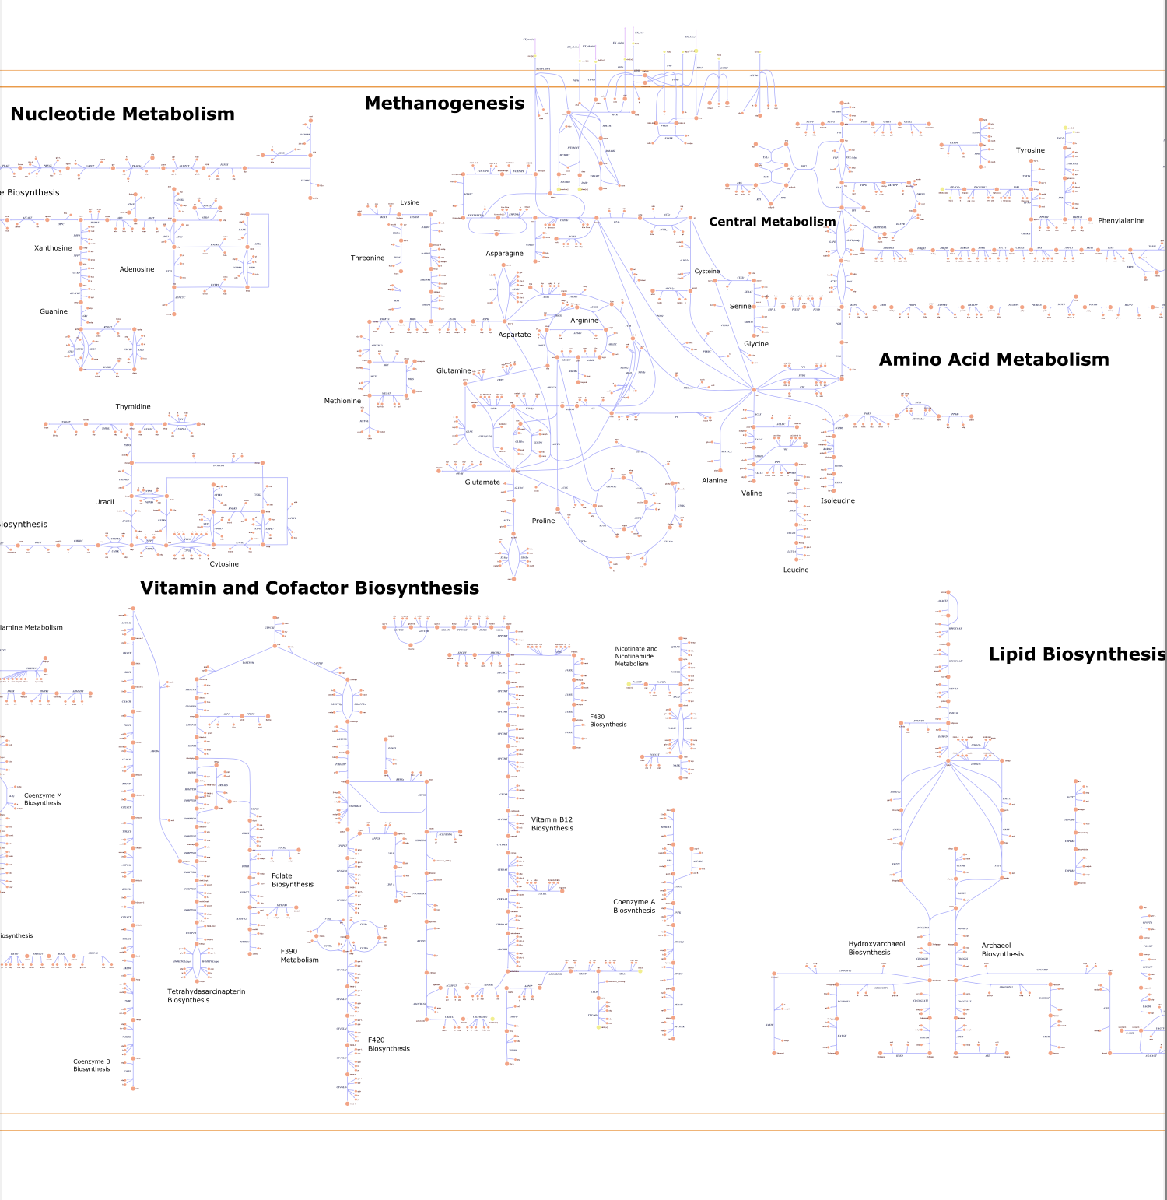

initCobraToolbox

% model.c(findRxnIDs(model,{'Mb_biomass_65'})) = 1;
model = readCbModel('mba_model.xml');

One subSystem per reaction, so each model.subSystems{x} is a character array.


model = struct with fields:
               S: [718×816 double]
            mets: {718×1 cell}
               b: [718×1 double]
          csense: [718×1 char]
            rxns: {816×1 cell}
              lb: [816×1 double]
              ub: [816×1 double]
               c: [816×1 double]
       osenseStr: 'max'
           genes: {750×1 cell}
           rules: {816×1 cell}
       geneNames: {750×1 cell}
       compNames: {2×1 cell}
           comps: {2×1 cell}
        proteins: {750×1 cell}
     metFormulas: {718×1 cell}
        metNames: {718×1 cell}
        rxnNames: {816×1 cell}
      subSystems: {816×1 cell}
     description: 'mba_model.xml'
    modelVersion: [1×1 struct]
         modelID: 'Mb_iUPDATE'


save('iGM746.mat', 'i746');
model = build_grRules(model);
FBAsolution = optimizeCbModel(model)

FBAsolution = struct with fields:
    origStatText: []
               f: 0.0208
              f0: NaN
              f1: 0.0208
              f2: NaN
               v: [816×1 double]
               y: [718×1 double]
               w: [816×1 double]
               s: [718×1 double]
          solver: 'gurobi'
        lpmethod: ''
            stat: 1
        origStat: 'OPTIMAL'
            time: 0.0157
           basis: [1×1 struct]
          vars_v: []
               x: [816×1 double]
             obj: 0.0208


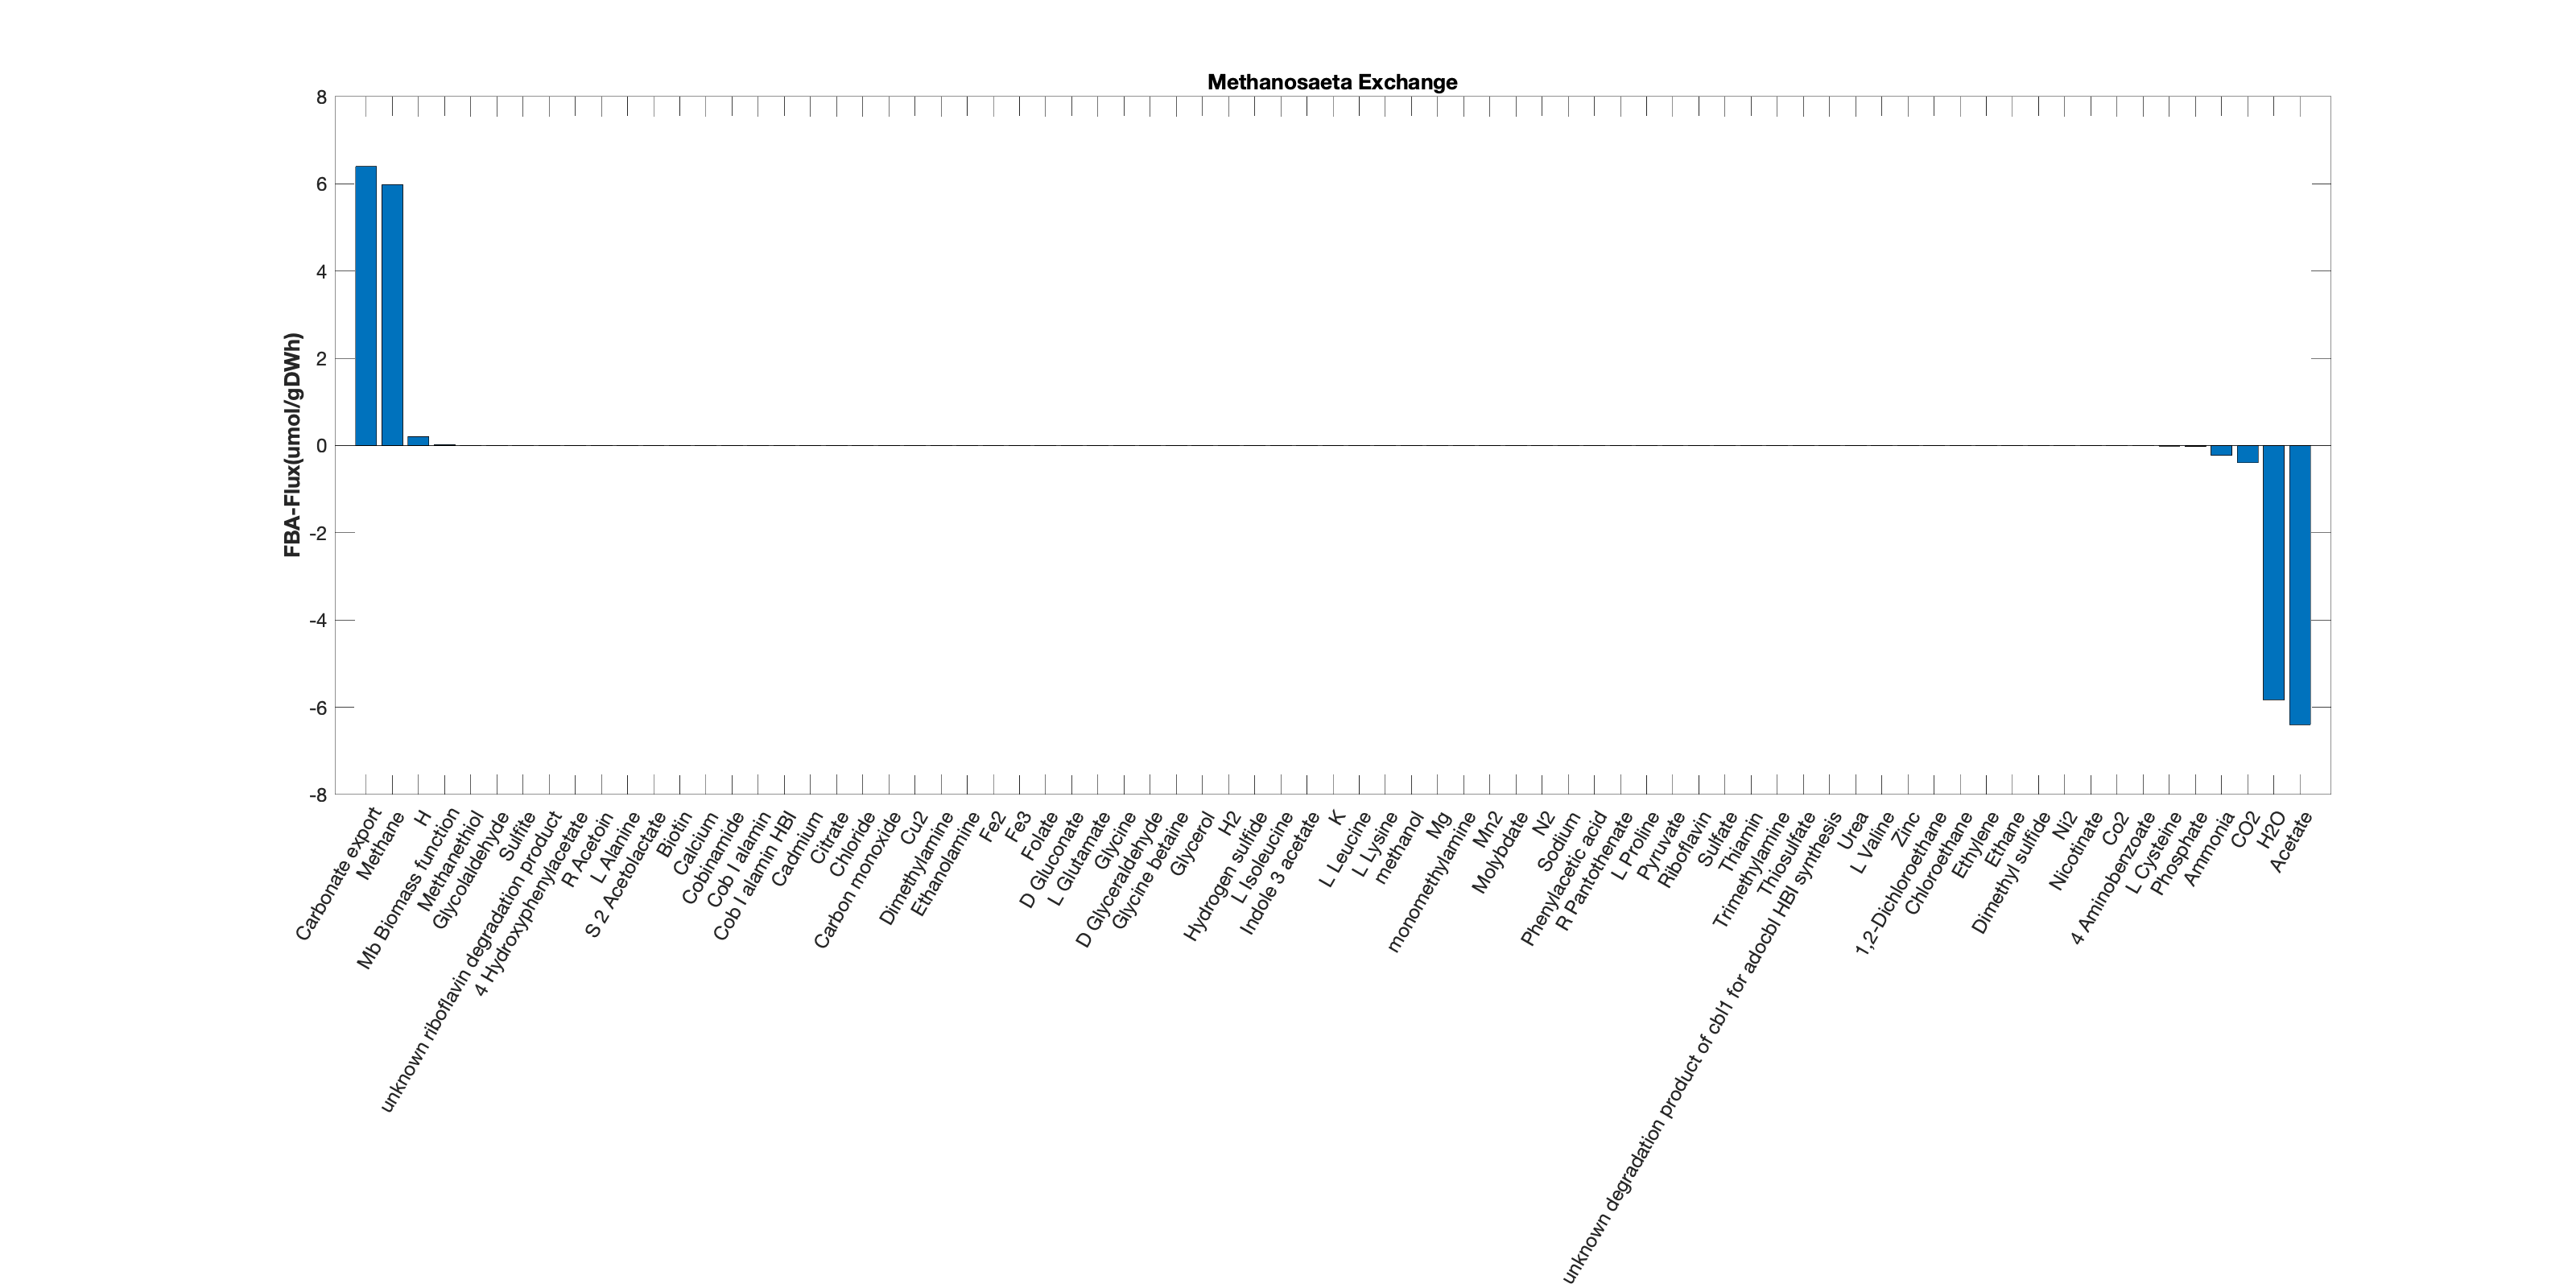

exchangeSubSystems = {'Exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"LPAREN e RPAREN");
c = erase(c,"exchange");

% c(find(contains(c,'_')))='-';

sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',12)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',14,'FontWeight','bold')
title(['Methanosaeta ',char(exchangeSubSystems)],'FontSize',12);

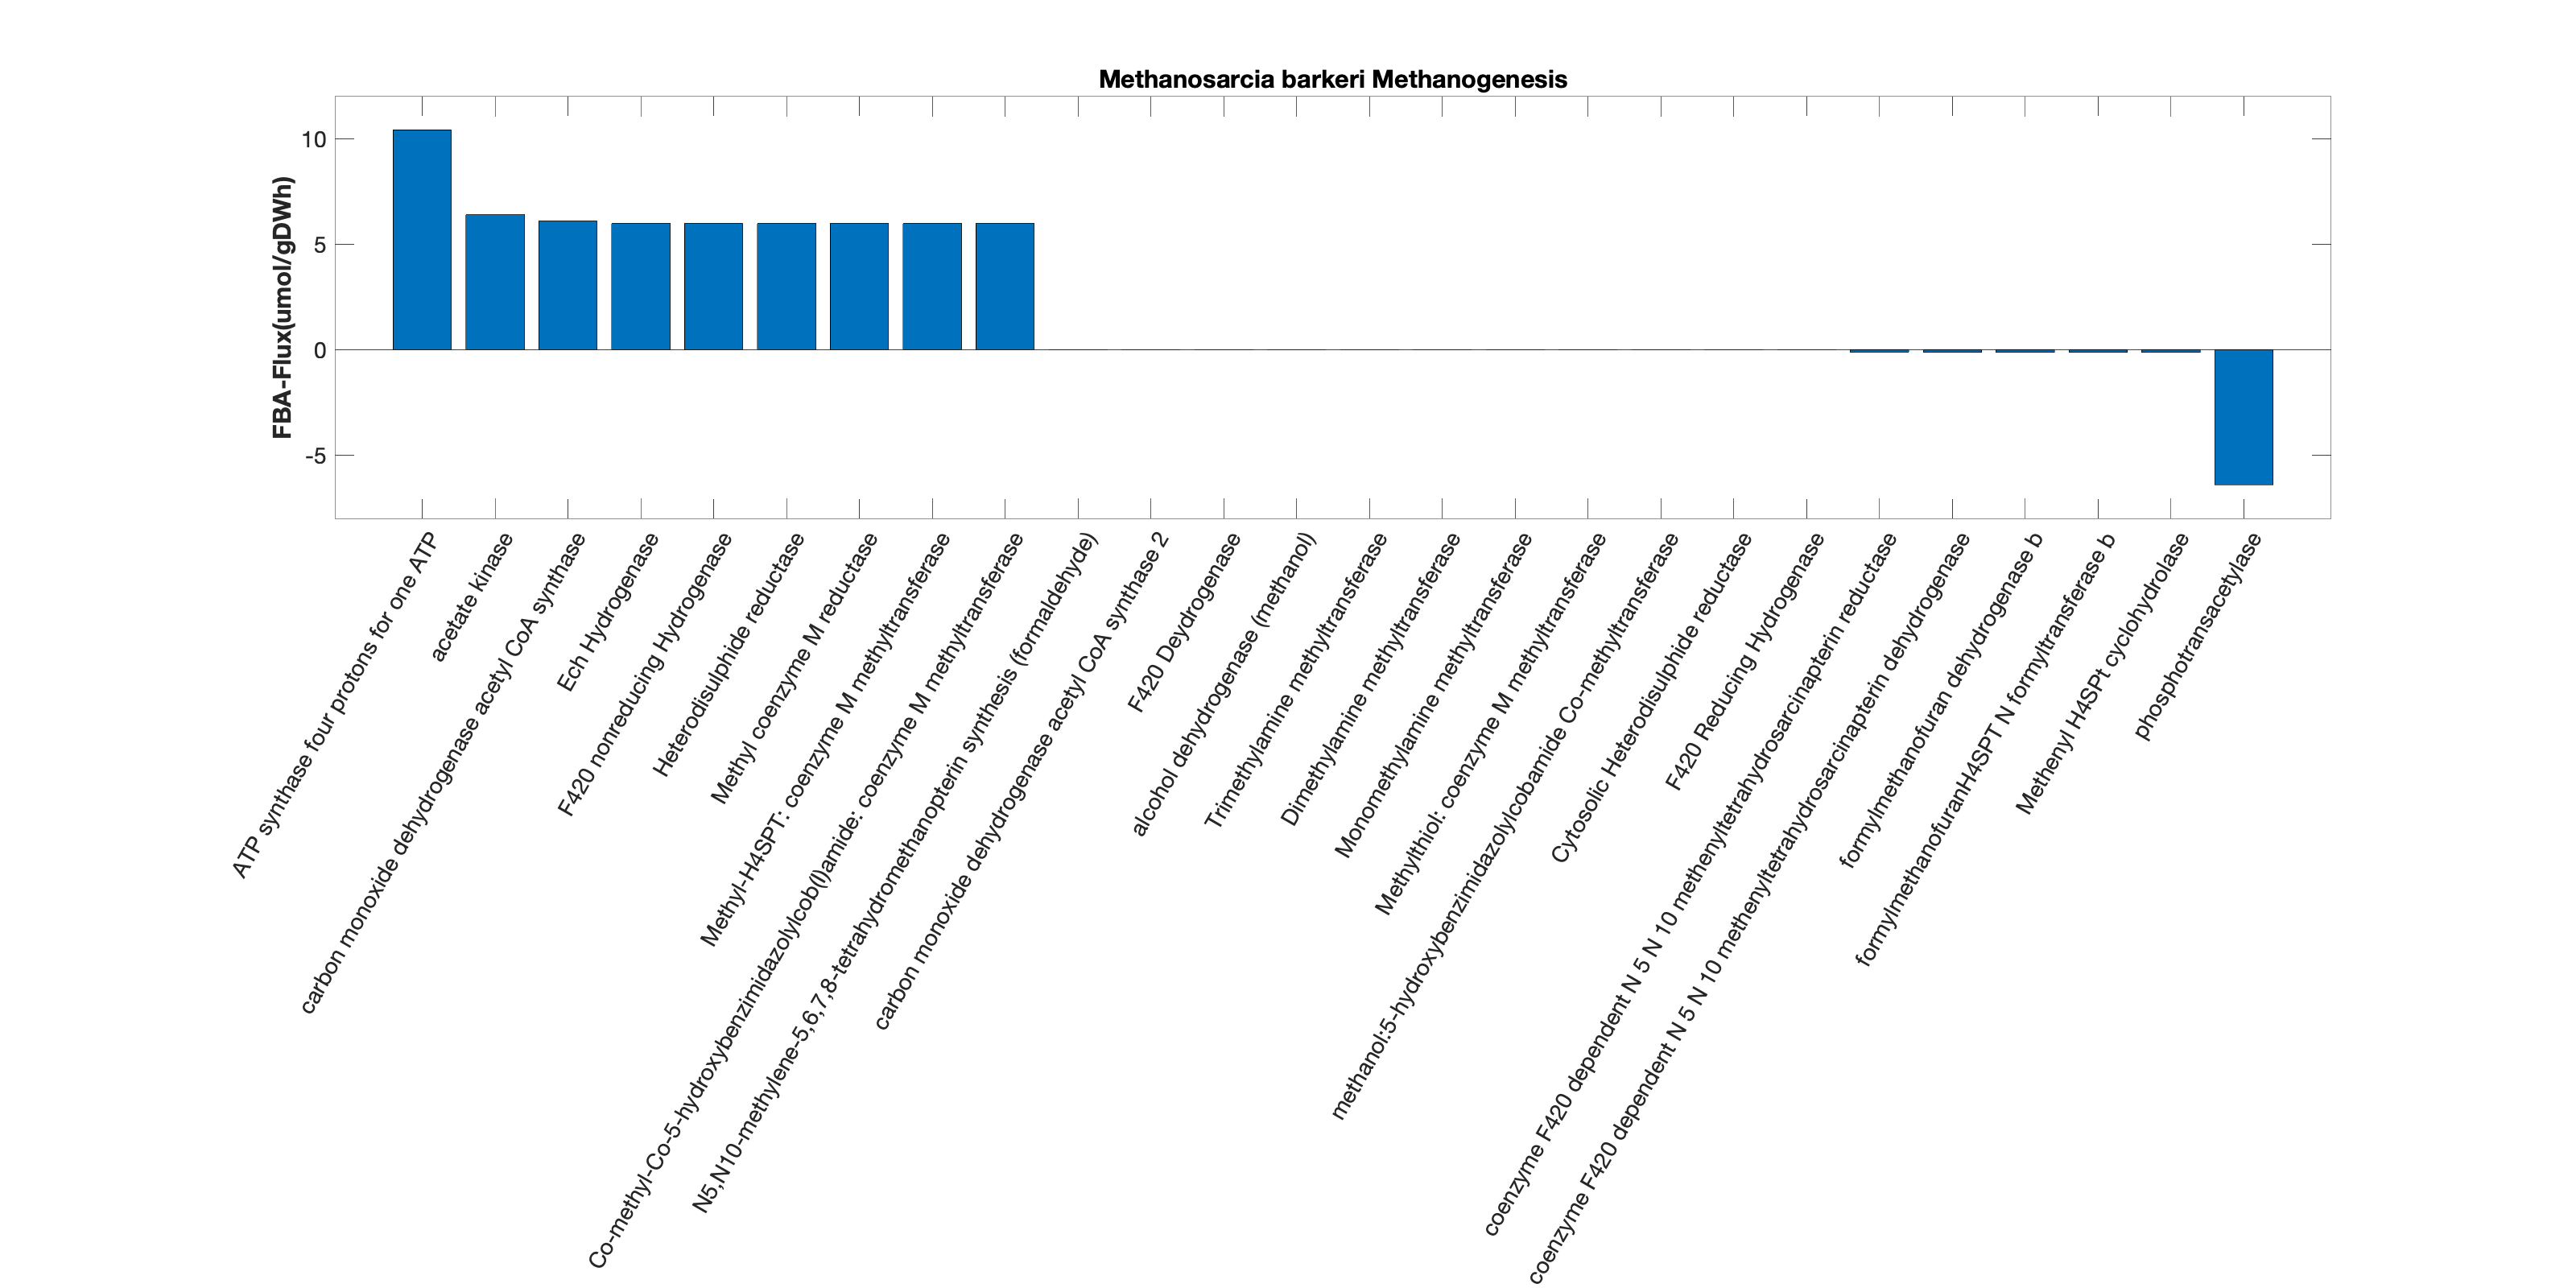

methanogenesisSubSystems =     {'Methanogenesis'};
methanogenesisReactions = model.rxns(ismember(model.subSystems,methanogenesisSubSystems));
[~,metanogenesis_rxnID] = ismember(methanogenesisReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(FBAsolution.v(metanogenesis_rxnID), 'descend');

c = string(categorical(model.rxnNames(metanogenesis_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"exchange");
sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(metanogenesis_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',14)
ylabel('FBA-Flux(umol/gDWh)', 'FontSize',16,'FontWeight','bold')
title(['Methanosarcia barkeri ',char(methanogenesisSubSystems)],'FontSize',16);

a = printRxnFormula(model,model.rxns(metanogenesis_rxnID(sortOrder)));

ATPS4r	adp[c] + 4 h[e] + pi[c] 	<=>	atp[c] + h2o[c] + 3 h[c] 
ACKr	ac[c] + atp[c] 	<=>	actp[c] + adp[c] 
CODHr	accoa[c] + 2 fdox[c] + h2o[c] + h4spt[c] 	<=>	co2[c] + coa[c] + 2 fdred[c] + 2 h[c] + mh4spt[c] 
ECHH_20	2 fdred[c] + 4 h[c] 	<=>	2 fdox[c] + h2[c] + 2 h[e] 
F4NH	h2[e] + 2 h[c] + mphen[c] 	<=>	2 h[e] + mphenh2[c] 
HDR	2 h[c] + hsfd[c] + mphenh2[c] 	->	cob[c] + com[c] + 2 h[e] + mphen[c] 
MCR	cob[c] + mcom[c] 	->	ch4[c] + hsfd[c] 
MTSPCMMT	h[c] + mh4spt[c] + 2 na1[c] + 5hbc_red[c] 	<=>	h4spt[c] + 2 na1[e] + m5hbc[c] 
CM5HBCMT	com[c] + m5hbc[c] 	->	h[c] + mcom[c] + 5hbc_red[c] 
FAE	fald[c] + h4spt[c] 	->	h2o[c] + mleneh4spt[c] 
CODH2	co[c] + 2 fdox[c] + h2o[c] 	->	co2[c] + 2 fdred[c] + 2 h[c] 
F4D	f420-2h2[c] + h[c] + mphen[c] 	->	f420-2[c] + 2 h[e] + mphenh2[c] 
ALCD1y	meoh[c] + nadp[c] 	<=>	fald[c] + h[c] + nadph[c] 
TMAMT	h[c] + tma[c] + 5hbc_red[c] 	->	dma[c] + m5hbc[c] 
DMAMT	dma[c] + h[c] + 5hbc_red[c] 	->	mma[c] + m5hbc[c] 
MMAMT	h[c] + mma[c] + 5hbc_red[c] 	->	nh4[c] + 

table(model.rxns(metanogenesis_rxnID),a, FBAsolution.v(metanogenesis_rxnID), model.grRules(metanogenesis_rxnID))

ans = 26×4 table
         Var1                                                           a                                                         Var3                                                                                                       Var4                                                                                               
    _______________    ____________________________________________________________________________________________________    ___________    __________________________________________________________________________________________________________________________________________________________________________________________________

    {'ACKr'       }    {'adp[c] + 4 h[e] + pi[c]  <=> atp[c] + h2o[c] + 3 h[c] '                                          }         6.3998    {'Mbar_A1820'                 

drawFlux(model, FBAsolution.v(metanogenesis_rxnID), 'reaction', model.rxns(metanogenesis_rxnID));

Unable to perform assignment because dot indexing is not supported for variables of this type.

Error in drawFlux (line 45)
    options.colorScale = cool(100);

## **entropicFBA**

param.solver ='mosek';
solution = entropicFluxBalanceAnalysis(model,param);

Using existing internal net flux bounds without modification.
Using existing external net flux bounds without modification.
Lower bound on forward flux is positive for the following internal reactions:
ATPM                 	           2
MOSEK ERROR. There is something wrong with MOSEK installation
             Please see the trouble shooting section the toolbox manual.


Output argument "r" (and maybe others) not assigned during call to "mosekopt".

Error in setMosekParam (line 11)
    [~, res] = mosekopt('symbcon echo(0)');

Error in solveCobraEP (line 553)
        [cmd, mosekParam] = setMosekParam(param);

Error in 

plot(solution.v)

exchangeSubSystems = {'Extracellular exchange'};
exchangeReactions = model.rxns(ismember(model.subSystems,exchangeSubSystems));
[~,exchange_rxnID] = ismember(exchangeReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(solution.v(exchange_rxnID), 'descend');

c = string(categorical(model.rxnNames(exchange_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"exchange");
sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(exchange_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',14)
ylabel('eFBA-Flux(umol/gDWh)', 'FontSize',16,'FontWeight','bold')
title(['Methanosarcia barkeri ',char(exchangeSubSystems)],'FontSize',16);

methanogenesisSubSystems =     {'Methanogenesis'};
methanogenesisReactions = model.rxns(ismember(model.subSystems,methanogenesisSubSystems));
[~,metanogenesis_rxnID] = ismember(methanogenesisReactions,model.rxns);
% printLabeledData(exchangeReactions,FBAsolution.v(exchange_rxnID),1)


[sorted_flux, sortOrder] = sort(solution.v(metanogenesis_rxnID), 'descend');

c = string(categorical(model.rxnNames(metanogenesis_rxnID)));
c= c(sortOrder);
sorted_flux(find(contains(c,'Transport of')))=[];
c(find(contains(c,'Transport of')))=[];

c = erase(c,"EX ");
c = erase(c,"exchange");
sorted_labels = c;
figure('Renderer', 'painters', 'Position', [10 10 1600 800])
bar(sorted_flux);

% printLabeledData(sorted_labels, sorted_flux,1)

[m, ~] = size(metanogenesis_rxnID);
set(gca,'XTick',[1:m],'xticklabel',sorted_labels)
set(gca,'XTickLabelRotation',60, 'FontSize',14)
ylabel('eFBA-Flux(umol/gDWh)', 'FontSize',16,'FontWeight','bold')
title(['Methanosarcia barkeri ',char(methanogenesisSubSystems)],'FontSize',16);
